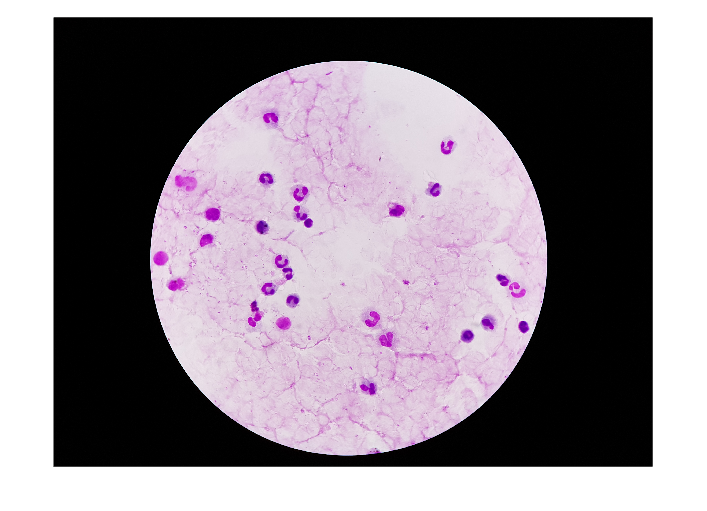

% --- Variables necesarias definidas previamente ---
IPF = imread('20170829_174225.jpg'); 
imshow(IPF)

Imagen_FILT = im2double(IPF);    
I_gray = rgb2gray(Imagen_FILT);    
I_gray_uint8 = im2uint8(I_gray);     

% Máscara del portaobjetos (campo de visión)
Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
fov_mask = segmentCellsStainBased(Imagen_mascara_gray); % Función externa

% Canal 3 (núcleo) de imagen deconvolucionada
OD = -log(Imagen_FILT + 0.01);
OD = reshape(OD, [], 3);
W_manual = [
    0.650, 0.072, 0.707; 
    0.704, 0.990, 0.707; 
    0.286, 0.117, 0.000
];
W = W_manual ./ vecnorm(W_manual, 2, 2);
W = W';
C = OD * inv(W);
deconvolved_manual = reshape(C, size(IPF));
Imagen_nucleos = deconvolved_manual(:,:,3);

% Aplicación de fov_mask y binarización de núcleos
bw = imbinarize(Imagen_nucleos);
Imagen_masked = bw .* fov_mask;

% Datos de parásitos reales
fileID = fopen('20170829_174225.txt', 'r');
lines = textscan(fileID, '%s', 'Delimiter', '\n'); fclose(fileID); lines = lines{1};
lines(1) = [];
data = cell(length(lines), 7); 
for i = 1:length(lines)
    tokens = strsplit(lines{i}, ',');
    for j = 1:7
        if j <= length(tokens)
            data{i, j} = tokens{j};
        else
            data{i, j} = '';
        end
    end
end
dataTable = cell2table(data, 'VariableNames', {'ID','Label','Comment','Shape','NumPoints','X1','Y1'});
dataTable.X1 = str2double(dataTable.X1); dataTable.Y1 = str2double(dataTable.Y1);
solo_parasitos = dataTable(ismember(dataTable.Label, {'Parasite', 'Parasitized'}), :);

## **SEGMENTACIÓN BASADO EN LOCAL THRESHOLDING**

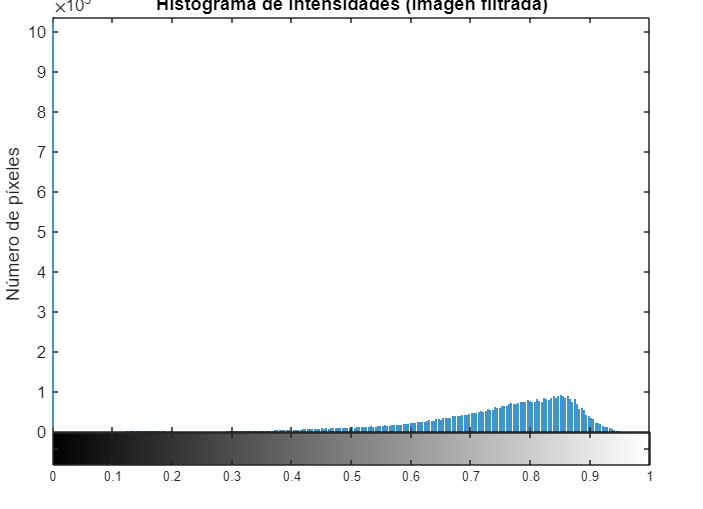

% Mejorar contraste y suavizar
I_eq = adapthisteq(I_gray);

% Aplicar máscara del portaobjetos (si es necesario)
BW_circle = imbinarize(I_eq, graythresh(I_eq));
BW_circle = imfill(BW_circle, 'holes');
BW_circle = bwareafilt(BW_circle, 1);
I_eq(~BW_circle) = 0;

% figure;
imhist(I_eq);
title('Histograma de intensidades (imagen filtrada)');
xlabel('Intensidad');
ylabel('Número de píxeles');

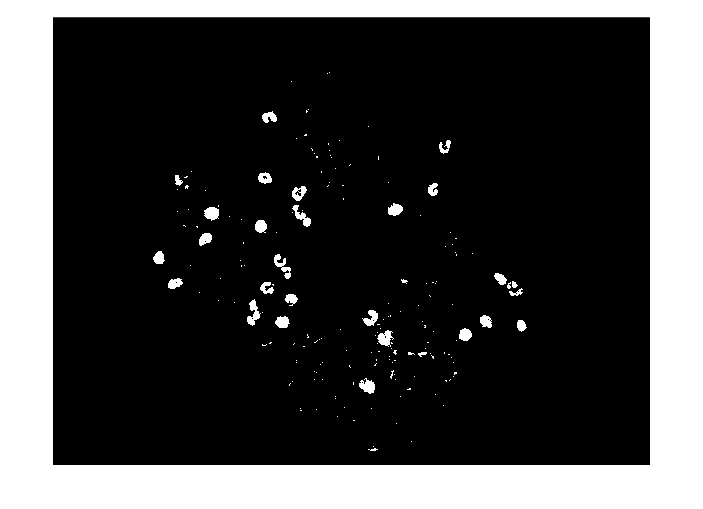


% Umbral por intensidad
umbral_bajo = 0.34;
mascara_oscuros = I_eq < umbral_bajo;
mascara_oscuros = mascara_oscuros .* fov_mask;
imshow(mascara_oscuros)

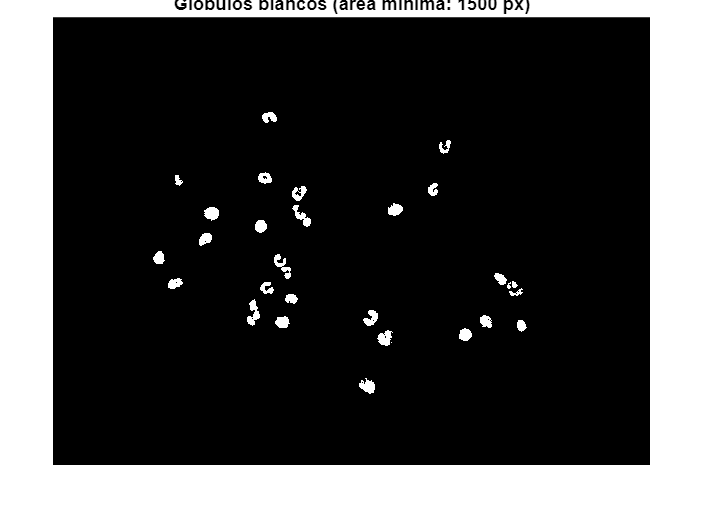


% Ajustable: tamaño mínimo de glóbulos blancos
tam_minimo = 1500;  
mascara_final = bwareafilt(logical(mascara_oscuros), [tam_minimo Inf]);

% Mostrar máscara final
figure;
imshow(mascara_final);
title(['Glóbulos blancos (área mínima: ', num2str(tam_minimo), ' px)']);

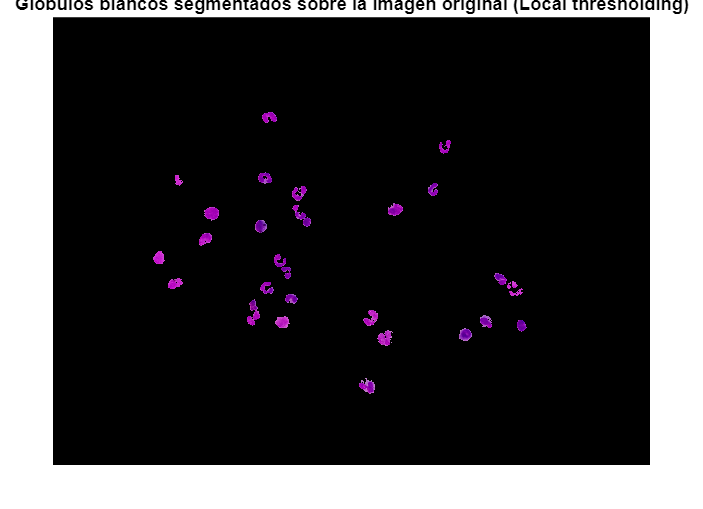


% Calcular propiedades de los glóbulos blancos segmentados
stats_local = regionprops(mascara_final, I_gray_uint8, {'Area', 'MeanIntensity', 'PixelIdxList'});

% Mostrar imagen con solo los glóbulos blancos segmentados
BW_RGB = repmat(mascara_final, 1, 1, 3); 
solo_globulos = Imagen_FILT;
solo_globulos(~BW_RGB) = 0; 
solo_globulos = solo_globulos .* fov_mask;
figure;
imshow(solo_globulos);
title('Glóbulos blancos segmentados sobre la imagen original (Local thresholding)');

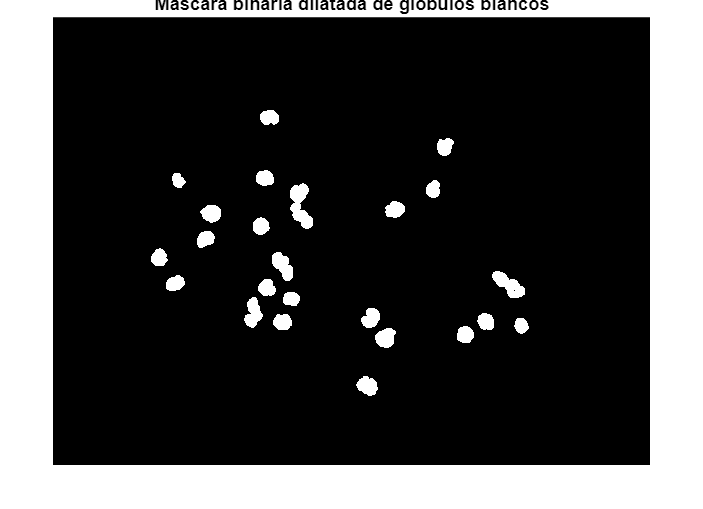


% Asegurarse que solo_globulos esté en escala de grises para binarizar correctamente
if size(solo_globulos, 3) == 3
    solo_globulos_gray = rgb2gray(solo_globulos);
else
    solo_globulos_gray = solo_globulos;
end

% Binarizar la imagen
solo_globulos_bin = imbinarize(solo_globulos_gray);

% Dilatar la máscara binaria
se = strel('disk', 15);
solo_globulos_dil = imdilate(solo_globulos_bin, se);

% Mostrar resultado
imshow(solo_globulos_dil);
title('Máscara binaria dilatada de glóbulos blancos');

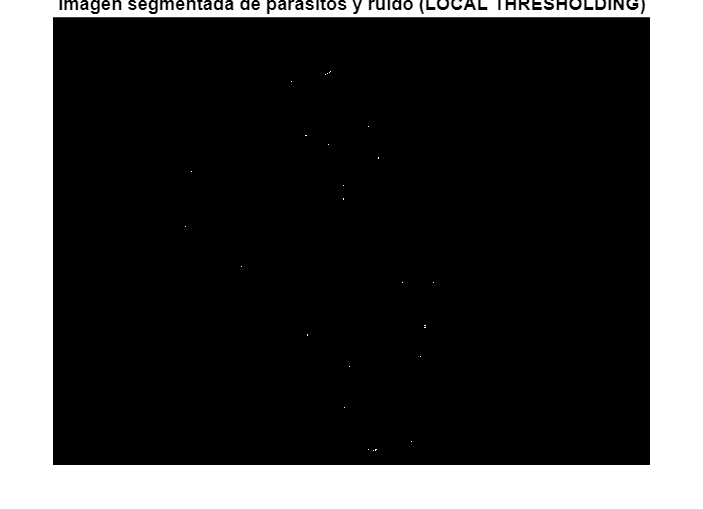


% Aplicar máscara para eliminar glóbulos blancos de la imagen
Imagen_masked_sin_GB = Imagen_masked;
Imagen_masked_sin_GB(solo_globulos_dil) = 0;

% Asegurar que la imagen está en escala de grises
if size(Imagen_masked_sin_GB, 3) == 3
Imagen_masked_sin_GB = rgb2gray(Imagen_masked_sin_GB);
end

bw_local = imbinarize(Imagen_masked_sin_GB, 'adaptive', 'ForegroundPolarity', 'dark', 'Sensitivity', 0.6);

% Filtrado morfológico para eliminar objetos pequeños (glóbulos blancos residuales, ruido)
umbral_tamano = 400;
bw_filtrado = filtrar_por_tamano(bw_local, umbral_tamano);

% Aplicar dilatación morfológica para engrosar los objetos
mascara_dilatada = bw_filtrado .* fov_mask;
solo_globulos_dil = imdilate(solo_globulos, strel('disk', 50));
solo_globulos_dil = rgb2gray(solo_globulos_dil);
solo_globulos_dil = imbinarize(solo_globulos_dil);
mascara_dilatada(solo_globulos_dil) = 0;
bw_local = imbinarize(mascara_dilatada, 'adaptive', ...
    'ForegroundPolarity', 'bright', 'Sensitivity', 0.6);

% Visualizar resultado del filtrado y dilatado
figure;
imshow(bw_local);
title('Imagen segmentada de parásitos y ruido (LOCAL THRESHOLDING)');


% Detección circular de parásitos
[centros_parasitos, radios_parasitos] = imfindcircles(bw_local, [2 5], 'Sensitivity', 0.92, 'EdgeThreshold', 0.5);

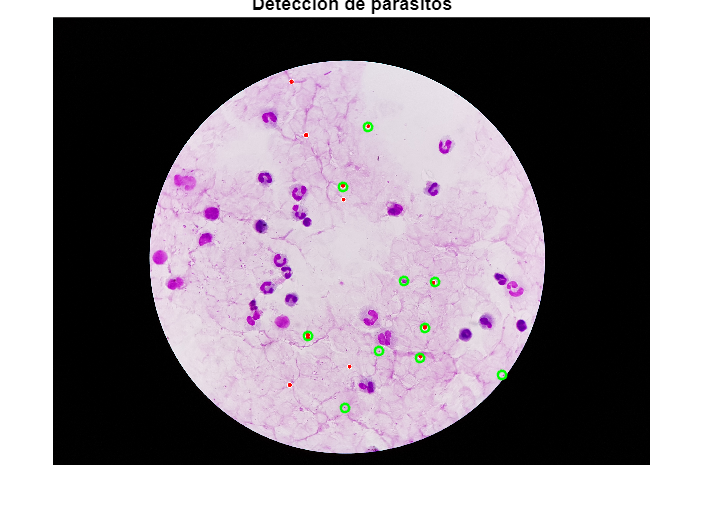


% Contar parásitos detectados automáticamente y reales
num_auto = size(centros_parasitos, 1);
num_reales = size(solo_parasitos, 1);
num_total = num_auto + num_reales;

% Mostrar resultados sobre imagen original
figure; imshow(IPF);
title('Detección de parásitos');
hold on;

% Dibujar círculos detectados (automáticos)
viscircles(centros_parasitos, radios_parasitos, 'EdgeColor', 'r');

% Dibujar parásitos reales (desde archivo)
plot(solo_parasitos{:,6}, solo_parasitos{:,7}, 'go', 'MarkerSize', 5, 'LineWidth', 1.5);

hold off;


% Mostrar información básica en consola
fprintf('Detectados: %d\nReales: %d\nTotal: %d\n', num_auto, num_reales, num_total);

Detectados: 13
Reales: 10
Total: 23



% Parámetro para ampliar el radio de los círculos si es necesario
radio_extra = 20; 

% Verificar cuántos parásitos reales caen dentro de algún círculo detectado
aciertos = 0;
for i = 1:size(solo_parasitos, 1)
    punto_real = [solo_parasitos{i,6}, solo_parasitos{i,7}];
    for j = 1:size(centros_parasitos, 1)
        centro_detectado = centros_parasitos(j,:);
        radio_detectado = radios_parasitos(j) + radio_extra; 
        
        % Calcular distancia entre el punto real y el centro del círculo
        distancia = norm(punto_real - centro_detectado);
        
        % Verificar si el punto real está dentro del círculo ampliado
        if distancia <= radio_detectado
            aciertos = aciertos + 1; 
            break; % Si se encuentra uno, no es necesario buscar más círculos para este punto real
        end
    end
end

% Calcular falsos positivos
falsos_positivos = num_auto - aciertos;
falsos_negativos = size(solo_parasitos,1) - aciertos;

% Mostrar en consola
fprintf('Parásitos correctamente detectados: %d de %d reales\n', aciertos, size(solo_parasitos,1));

Parásitos correctamente detectados: 6 de 10 reales


fprintf('Falsos positivos: %d\n', falsos_positivos);

Falsos positivos: 7


fprintf('Falsos negativos: %d\n', falsos_negativos);

Falsos negativos: 4


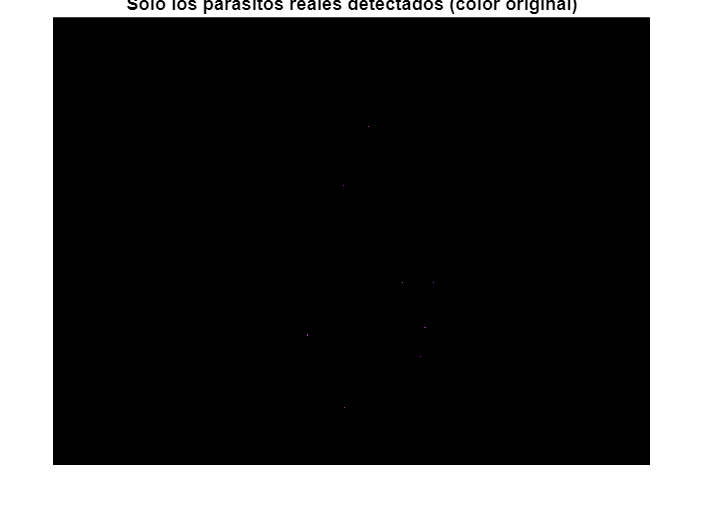


x_real = solo_parasitos{:,6};
y_real = solo_parasitos{:,7};
props = regionprops(bw_local, 'Centroid', 'Area', 'Perimeter', 'PixelIdxList');
indices_objetos = zeros(length(x_real), 1);

% 5. Cálculo de propiedades de los objetos reales 
areas = zeros(length(x_real), 1);
circularidades = zeros(length(x_real), 1);

bw_parasitos = false(size(bw_local));

for i = 1:length(x_real)
    % Obtener todos los centroides
    centroides = reshape([props.Centroid], 2, [])'; % Nx2 (x,y)
    % Calcular distancias al punto real i
    distances = sqrt((centroides(:,1) - x_real(i)).^2 + (centroides(:,2) - y_real(i)).^2);
    % Índice del objeto con centroide más cercano
    [~, idx] = min(distances);
    indices_objetos(i) = idx;
end

% Extraer canales
R = IPF(:,:,1); G = IPF(:,:,2); B = IPF(:,:,3);
intensidades_R = zeros(length(x_real),1);
intensidades_G = zeros(length(x_real),1);
intensidades_B = zeros(length(x_real),1);

bw_parasitos = false(size(bw_local));

for i = 1:length(indices_objetos)
    idx = indices_objetos(i);
    obj = props(idx);
    areas(i) = obj.Area;
    if obj.Perimeter > 0
        circularidades(i) = 4 * pi * obj.Area / (obj.Perimeter^2);
    else
        circularidades(i) = NaN;
    end

    % Acumular máscara total
    bw_parasitos(obj.PixelIdxList) = true;

    % Intensidad media RGB por objeto
    intensidades_R(i) = mean(R(obj.PixelIdxList));
    intensidades_G(i) = mean(G(obj.PixelIdxList));
    intensidades_B(i) = mean(B(obj.PixelIdxList));
end

% 7. Visualización final: solo los parásitos reales en color 
parasitos_color = zeros(size(IPF), 'like', IPF);
for canal = 1:3
    temp = IPF(:,:,canal);
    temp(~bw_parasitos) = 0;
    parasitos_color(:,:,canal) = temp;
end

figure;
imshow(parasitos_color);
title('Solo los parásitos reales detectados (color original)');

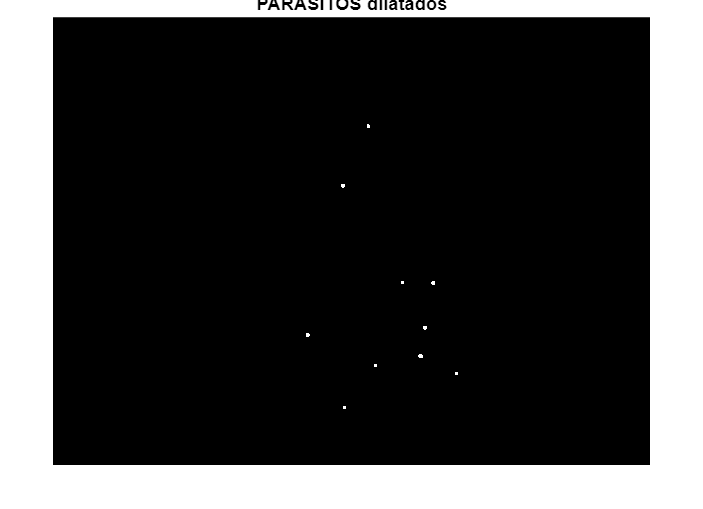


% 8. Dilatación de la imagen en color y creación de máscara en B/N
parasitos_gris = rgb2gray(parasitos_color);

% Crear una imagen binaria desde la imagen en escala de grises
bw_parasitos_color = parasitos_gris > 0;

% Dilatar la máscara binaria
se = strel('disk', 10);  
bw_parasitos_dilatada = imdilate(bw_parasitos_color, se);

% Mostrar la máscara dilatada
figure;
imshow(bw_parasitos_dilatada);
title('PARÁSITOS dilatados');

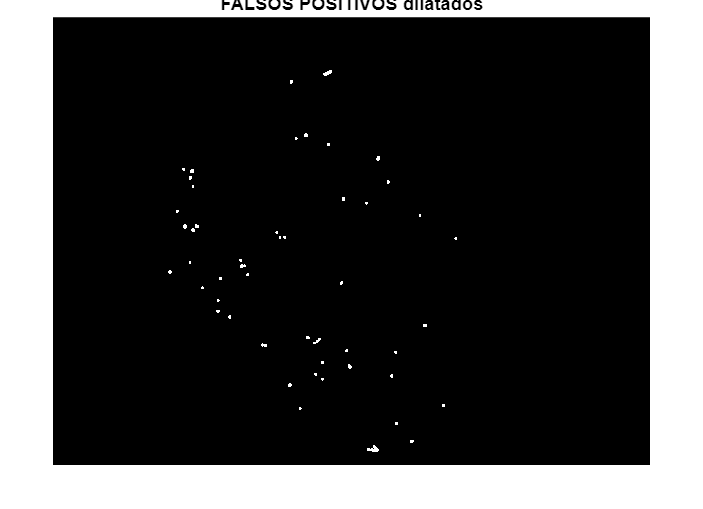


% Invertir la máscara binaria de parásitos dilatada
mascara_parasitos_invertida = ~bw_parasitos_dilatada;

% Aplicar la máscara invertida a la imagen segmentada
bw_falsos_positivos = bw_local & mascara_parasitos_invertida;
bw_falsos_positivos=imdilate(bw_falsos_positivos, se);

% Mostrar el resultado
figure;
imshow(bw_falsos_positivos);
title('FALSOS POSITIVOS dilatados');

function fov_mask  = segmentCellsStainBased(I)

    if size(I, 3) == 3
        I = rgb2gray(I);
    end
   
    level = graythresh(I);
    bw = imbinarize(I, level);
   
    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end
   
    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');

    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');
   
    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;
   
    adjusted_radius = max(circle_radius - 15, 0);
   
    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);

    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;

end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

% Función REGION GROWING
function region_mask = regionGrowing(img, seed_point, intensity_thresh, max_size)
    region_mask = false(size(img));
    to_visit = seed_point;
    region_intensity_mean = double(img(seed_point(2), seed_point(1)));
    count = 0;
    while ~isempty(to_visit) && count < max_size
        current = to_visit(1,:);
        to_visit(1,:) = [];
        x = current(1);
        y = current(2);
        
        if x<1 || y<1 || x>size(img,2) || y>size(img,1)
            continue;
        end
        
        if region_mask(y,x)
            continue; % ya visitado
        end
        
        intensity = double(img(y,x));
        if abs(intensity - region_intensity_mean) <= intensity_thresh
            region_mask(y,x) = true;
            count = count + 1;
            % Añadir vecinos 8-conectados
            vecinos = [x-1,y-1; x,y-1; x+1,y-1; x-1,y; x+1,y; x-1,y+1; x,y+1; x+1,y+1];
            to_visit = [to_visit; vecinos]; % añadir al final
            % Actualizar intensidad media
            region_intensity_mean = (region_intensity_mean*(count-1) + intensity) / count;
        end
    end
end